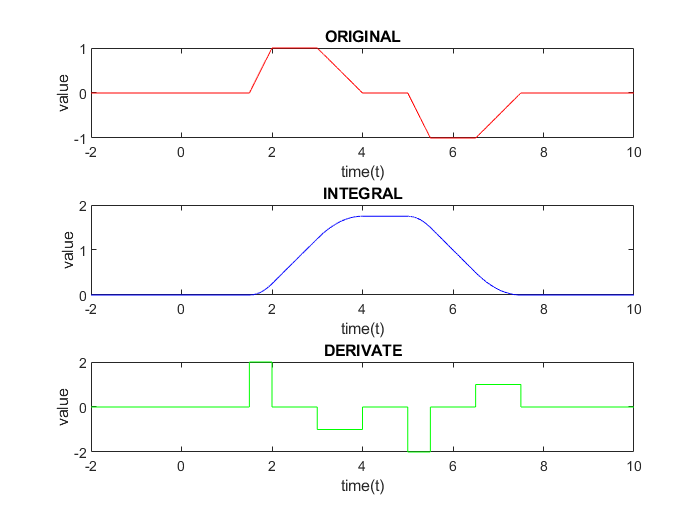


t=-2:0.001:10;
x1=signal(t);
x2=integral(t);
x3=derivate(t);
figure
subplot(3,1,1)
plot(t,x1,'r')
title('ORIGINAL')
xlabel('time(t)')
ylabel('value')

subplot(3,1,2)
plot(t,x2,'b')
title('INTEGRAL')
xlabel('time(t)')
ylabel('value')

subplot(3,1,3)
plot(t,x3,'g')
title('DERIVATE')
xlabel('time(t)')
ylabel('value')

function x=signal(t)
    x=(2*ctramp(t-1.5))-(2*ctramp(t-2))-ctramp(t-3)+ctramp(t-4)-2*ctramp(t-5)+2*ctramp(t-5.5)+ctramp(t-6.5)-ctramp(t-7.5);
end
function y=integral(t)
    y=(ctramp(t-1.5).*(t-1.5))-(ctramp(t-2).*(t-2))-(ctramp(t-3).*(t-3)/2)+(ctramp(t-4).*(t-4)/2)-(ctramp(t-5).*(t-5))+(ctramp(t-5.5).*(t-5.5))+(ctramp(t-6.5).*(t-6.5)/2)-(ctramp(t-7.5).*(t-7.5)/2);
end
function z=derivate(t)
    z=(2*ctstep(t-1.5))-(2*ctstep(t-2))-ctstep(t-3)+ctstep(t-4)-(2*ctstep(t-5))+(2*ctstep(t-5.5))+ctstep(t-6.5)-ctstep(t-7.5);
end